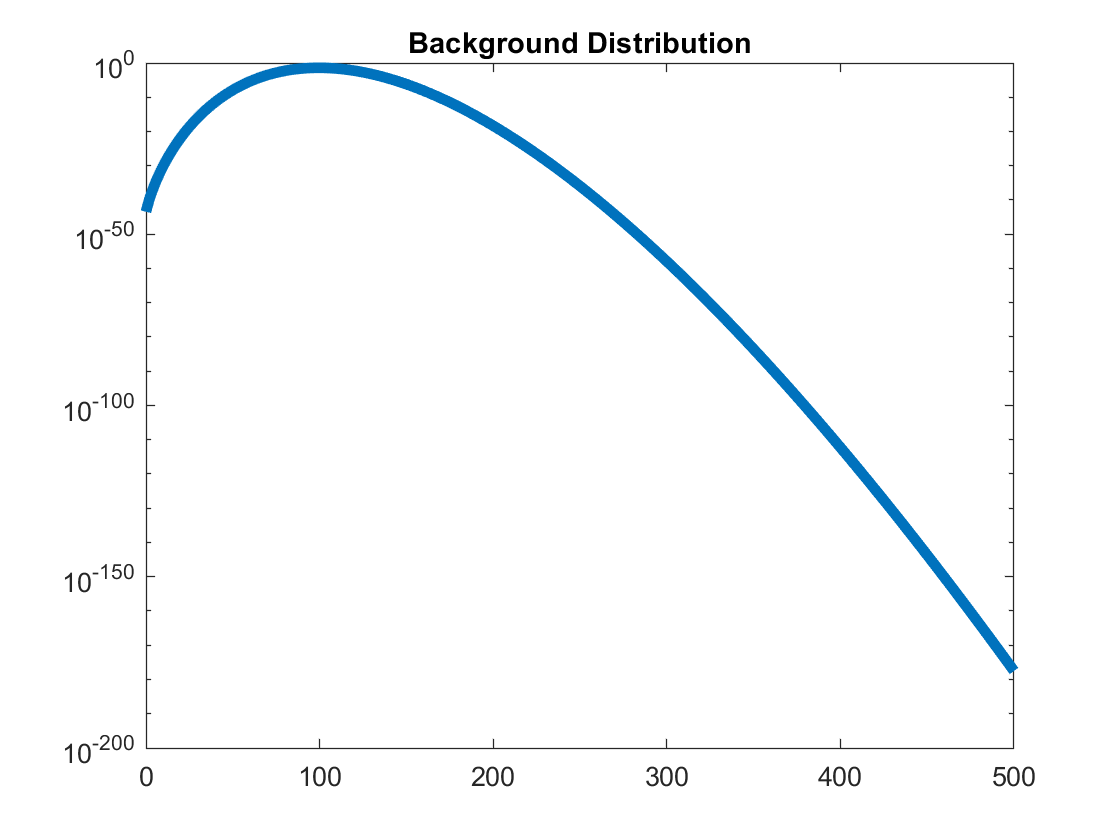

clear, close all, clc

x = 0:500;
pois = makedist('Poisson', 'Lambda',100);

semilogy(x,pdf(pois, x), 'Linewidth', 4)
title('Background Distribution')

bkgd = pdf(pois, x);

sig5thresh = sigthresh(x,100,5)

sig5thresh = 153

The 5 sigma threshold is 153.


sig8thresh = sigthresh(x,100,8)

sig8thresh = 191

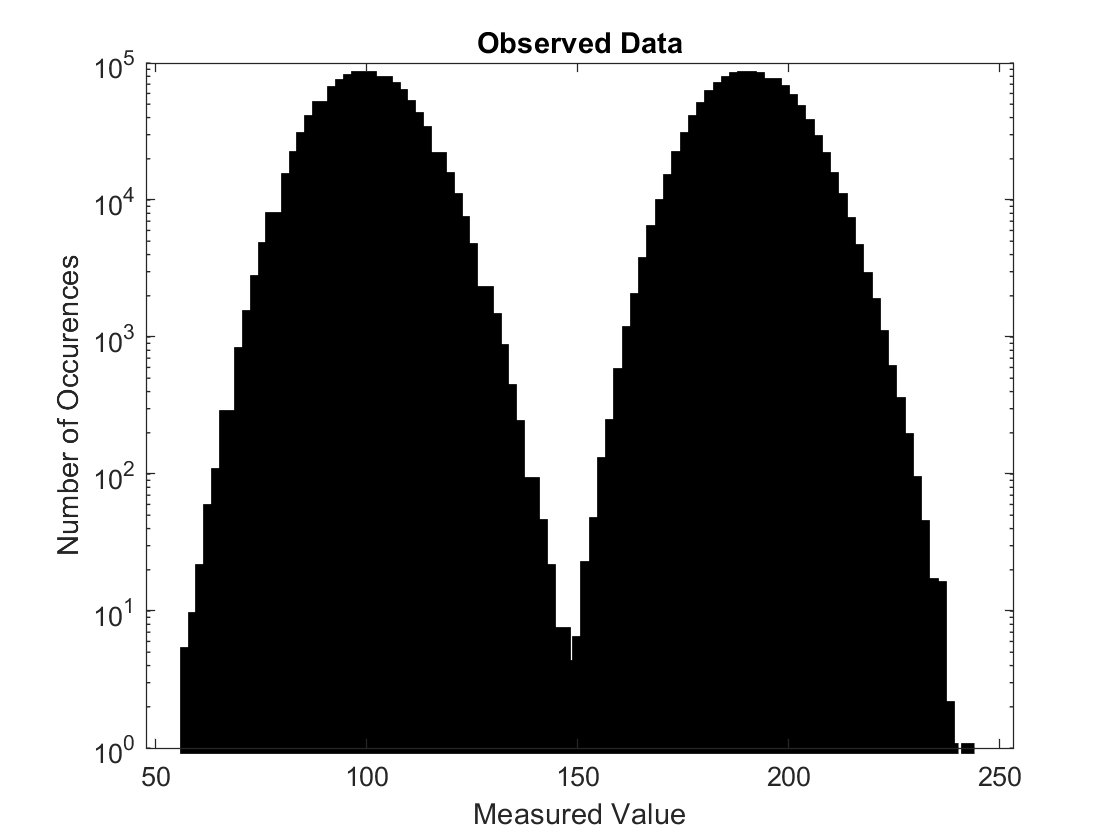


bkgd = poissrnd(100,1,1000000);
bkgd2 = poissrnd(100,1,1000000);
sig = bkgd2+91;
%bkgd(1,5001:5150) = poissrnd(sig8thresh,1,150);

histogram(bkgd,50, 'Linewidth', 4)
hold on
histogram(sig,50, 'Linewidth', 4)
set(gca,'YScale','log')
hold off
title('Observed Data')
xlabel('Measured Value')
ylabel('Number of Occurences')

The histogram is telling us that there is a very bright spike at the 8 sigma detection threshold. Other then the spike at 191 the histogram looks like an ordinary poisson distribution with a mean of 100. The observed signal is equally likely to the background. Behavior similar to this might occur if you are looking for something very obvious but also different from the background, for example the sun from the sky. This histogram is symetric.

## Problem 3

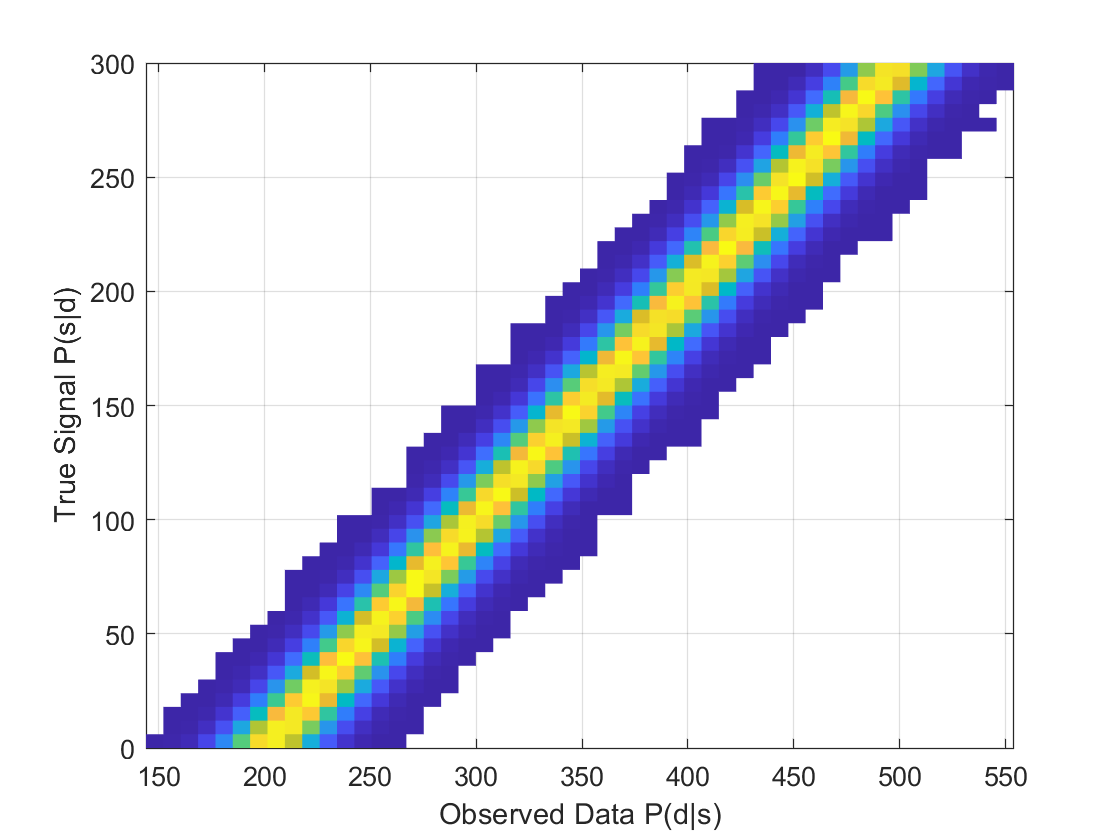

bkgd = poissrnd(100,1,1000000);
bkgd2 = poissrnd(100,1,1000000);
sig = 300*rand(1,1000000);

data = bkgd2+ bkgd + sig;

histogram2(data,sig,50,'DisplayStyle', 'tile');
xlabel('Observed Data P(d|s)')
ylabel('True Signal P(s|d)')

In the 2D histogram we are ploting the distribution of the observed data (essentialy everything that we are able to see) against the true signal or in this case the signal that we manually injected into the background data to create the observed signal. Since the injected data is uniformly distributed the "slope" of the 2D histogram is linear. Essentially we are just shifting the mean of the 1D signal histogram.

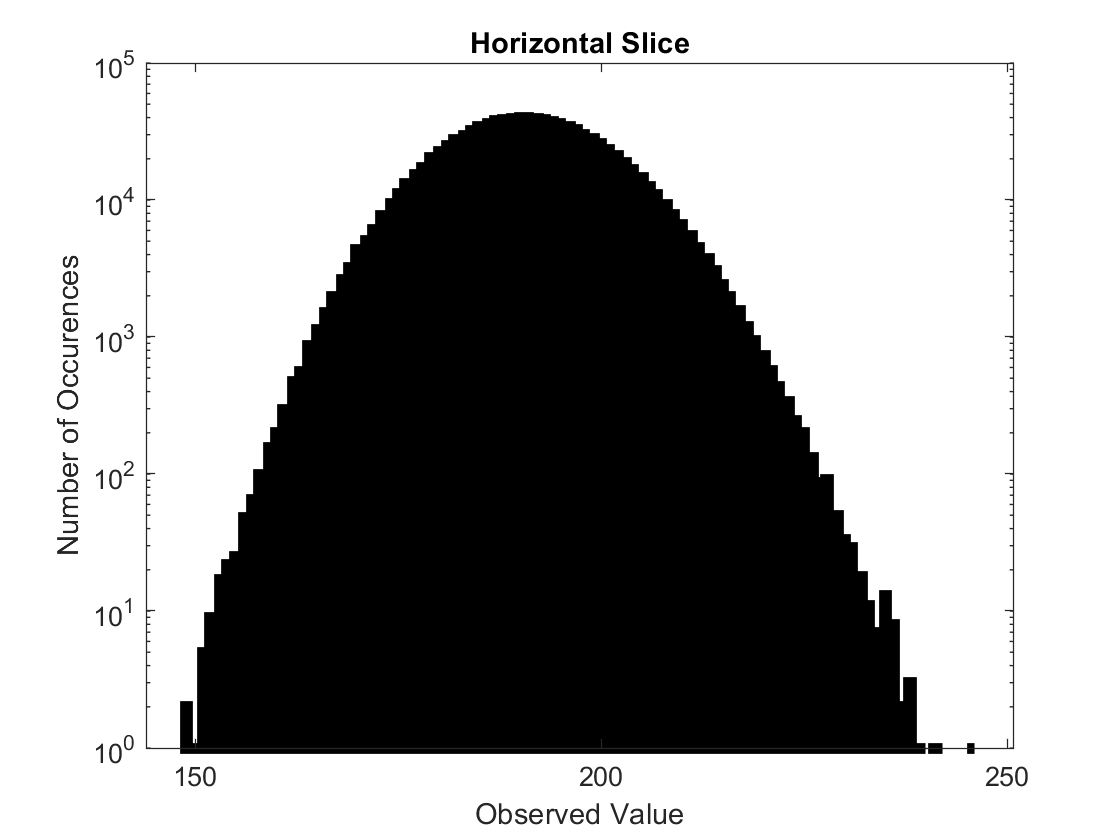

histogram(bkgd + 91,'Linewidth', 4)
title('Horizontal Slice')
xlabel('Observed Value')
ylabel('Number of Occurences')
set(gca,'YScale','log')

This agrees with the plot from Problem 2. Essentially this plot selects a true signal value from the 2D histogram and plots the corresponding horizontal slice.

histogram(300-bkgd,'Linewidth', 4)
title('Vertical Slice')
xlabel('True Signal Value')
ylabel('Number of Occurences')
set(gca,'YScale','log')

This plot selects a observed data value from the 2D histogram and plots the corresponding vertical slice.

m = mean(300-bkgd)

m = 200.0058

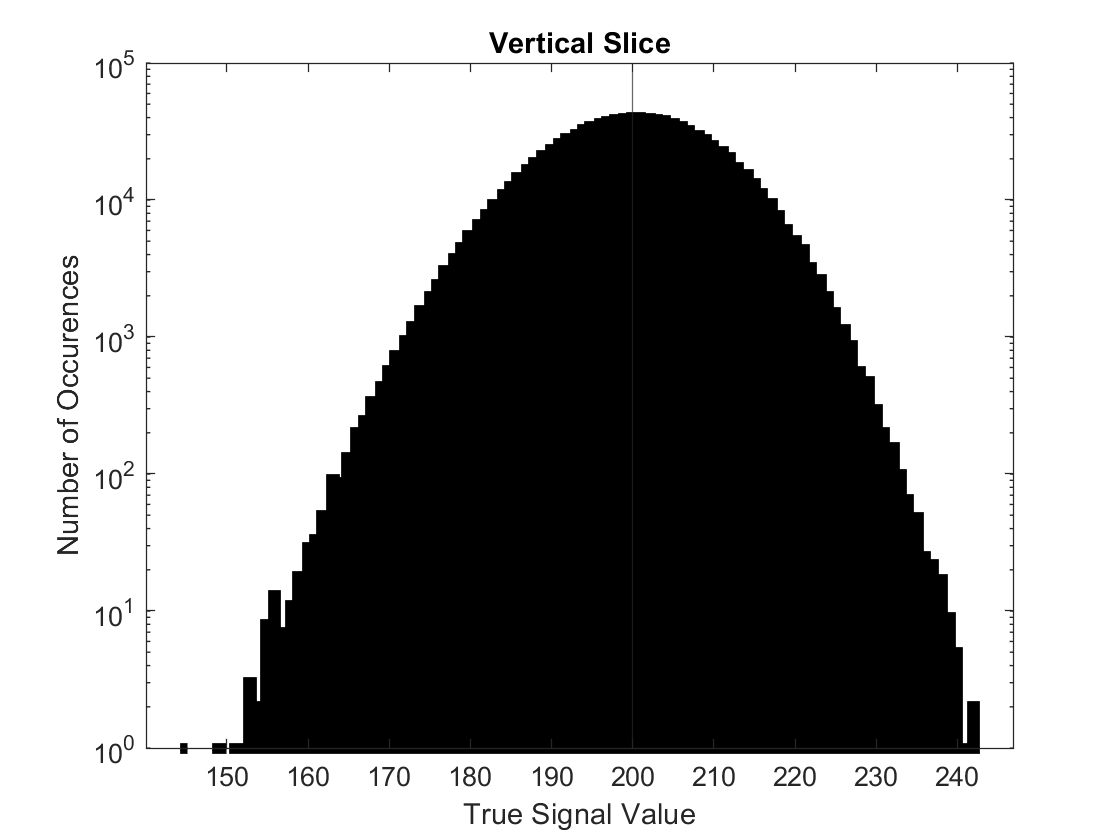

hold on
xline(m)


sig = 300-bkgd;
sl = 0;
su = 0;
for x = 1:length(sig)
    if sig(x) > m - 10.8446435 && sig(x) < m
        sl  = sig(x) + sl;
    end
    if sig(x) < m + 9.4394145 && sig(x) > m
        su  = sig(x) + su;
    end
end
percent_up = 100*su/(sum(sig))

percent_up = 32.3321

margin34up = m + 9.43941445

margin34up = 209.4452

percent_down = 100*sl/(sum(sig))

percent_down = 35.8342

margin34down = m - 10.8446435

margin34down = 189.1611

The margin for a 1 sigma probability above the mean is approximately 9.4394 and the margin for 1 sigma below the mean is approximately 10.8446. The plot is not symmetric as the margins for 1 sigma are different above and below the mean value. 

function [thresh] = sigthresh(x,mean_val,sig)
poisson = makedist("Poisson", 'lambda',mean_val);
prob_sig = 1-1/(1/(1-erf(sig/(sqrt(2)))));
y_vals = pdf(poisson,x);
for i = 1:length(x)
    check = sum(y_vals(1:i));
    if check > prob_sig
        thresh = i;
        break
    end
end
end